**Final Project Assessment 2: Detecting Cars in the video**

- *Detecting Moving Cars in a Video*

- *Inserting Bounding Box on the Cars*

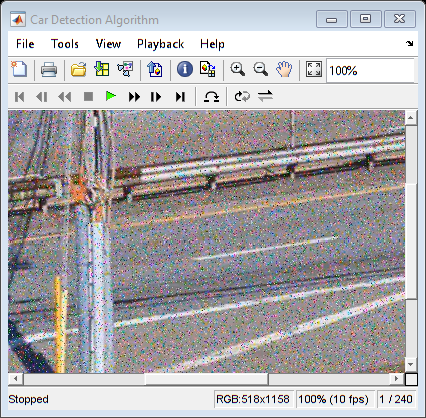

% Reading Input Video File &
% Creating output Video File with same FrameRate as Input Video File
Vin = VideoReader("RoadTraffic.mp4");
nFrames = Vin.NumFrames;
Vout = VideoWriter("CarDetection.mp4", "MPEG-4");
Vout.FrameRate = Vin.FrameRate;
open(Vout);

% Initializing Arrays and Counter Variables:
NumRegionArray = zeros(1);
MeanRegionArray = zeros(1);
TotalRegionArray = zeros(1);
Car_counter = zeros(1);
CountOneCar = 0;

Background = im2double(read(Vin,1)); % Setting Frame1 as Background

% Loop through the video: 
%   1. Enhace the frames using Gaussian Filter (function img = enhanceImage(img))
%   2. Take the difference between Background and Foreground to segment Cars
%   3. Use function [BW,maskedImage] = segmentImage(X) to create Binary
%      segmented Img
%   4. Use regionprops to get the Area of all detected Objects
%   5. Use bwpropfilt to set threshold to detect only the Cars and 
%      leave small regions
%   6. Use regionprops to get BoundingBox coordinates and Area of the Cars
%   7. Insert Bounding Box on the detected Cars
%   8. Put the Bounding Box in the Output Video
%   9. Calculate CarsperFrame and Area of the Cars
%   10. Add the Calculated values in the Arrays
%   11. Use IF condition to count Cars
for n = 1:nFrames
    Frame = im2double(read(Vin,n));
    EnhanceI = enhanceImage(Frame);
    frameDiff = abs(EnhanceI - Background);
    [binaryImg, MaskedImg] = segmentImage(frameDiff);  

    EntireImg = regionprops("table",binaryImg,"Area");
    CarRegions = bwpropfilt(binaryImg,'Area',[500 Inf]); 
    CarRegionProps = regionprops("table",CarRegions,"Area","BoundingBox");
    
    CarsDetected = insertShape(Frame,"Rectangle",CarRegionProps.BoundingBox,"LineWidth",4,"Color","yellow");
    
    writeVideo(Vout,CarsDetected); 
    
    NumberRegions = height(CarRegionProps);
    MeanRegionSize = mean((CarRegionProps.Area));
    TotalRegionSize = sum((CarRegionProps.Area));
    
    NumRegionArray(n) = NumberRegions;
    MeanRegionArray(n) = MeanRegionSize;
    TotalRegionArray(n) = TotalRegionSize;
    
    if NumRegionArray(n) >= 1
        CountOneCar = CountOneCar + 1; 
        Car_counter = Car_counter + NumberRegions; 
    end        
end
close(Vout)
OutputVid = implay("CarDetection.mp4");
set(OutputVid.Parent, 'Name', 'Car Detection Algorithm'); % Give title to the Video


% Transpose the Arrays:
NumRegionArray = NumRegionArray';
MeanRegionArray = MeanRegionArray';
TotalRegionArray = TotalRegionArray';

AvgRegionArray = sum(TotalRegionArray/Car_counter); % Calculate Average Region

% Create a Table to display the Data:
DataOutput = table(NumRegionArray,TotalRegionArray,MeanRegionArray,...
    'VariableNames',{'CarsPerFrame',...
    'TotalArea', 'MeanArea', })

DataOutput = 240×3 table
    CarsPerFrame    TotalArea    MeanArea
    ____________    _________    ________

         0                0          NaN 
         0                0          NaN 
         0                0          NaN 
         0                0          NaN 
         0                0          NaN 
         2             3822         1911 
         2            16379       8189.5 
         2            27458        13729 
         2            25424        12712 
         2            24217        12108 
         2            21777        10888 
         2            25157        12578 
         2            24221        12110 
         2            22775        11388 
         4            19478       4869.5 
         3            32774        10925 



% Display the Variables:
disp(['Atleast one Car detected in the video in a Frame: ', num2str(CountOneCar)])

Atleast one Car detected in the video in a Frame: 154


disp(['Average Region Area in the video: ', num2str(AvgRegionArray)])

Average Region Area in the video: 12559.588


**Noise Removal Function**

function img = enhanceImage(img)
fGaussian = fspecial("gaussian",[5,5],10);
imgGaussian = imfilter(img, fGaussian);
img = im2gray(imgGaussian);
end

**Image Segmentation Function**

function [BW,maskedImage] = segmentImage(X)
%segmentImage Segment image using auto-generated code from imageSegmenter app
%  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
%  code from the imageSegmenter app. The final segmentation is returned in
%  BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 24-Apr-2023
%----------------------------------------------------

X = im2gray(X);

% Threshold image - manual threshold
BW = X > 3.019600e-01;

% Open mask with disk
radius = 1;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% Close mask with disk
radius = 24;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imclose(BW, se);

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end